Based on software from "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Designing the Mobius Ring

Volker Ziemann, 211231, GPLv3

**Important:** this script uses the 5D beam optics routines, which are assumed to be available in a subdirectory called ./5D which is made accessible with `addpath ./5D`.

In this script we design the racetrack-shaped Mobius ring from 

- V. Ziemann, *Beam parameters of a Mobius ring*, FREIA Report 2022/01, forthcoming.

which is based on $90^o$ FODO cells.  First we define the basic cell in the arcs and in the dispersion suppressor. Then we design the Mobius straight section to adjust the coupling and the straight section to adjust the tunes. Finally we assemble the ring, caluclate the beta functions and tunes, as well as the radiation integrals, based on the new method from 

- V. Ziemann, A. Streun,* Equilibrium parameters in coupled storage ring lattices and practical applications*, forthcoming.

Finally all beam parameters are displayed in a table.

clear; close all
global beamline sigma0 D0       % pass parameters to fitting functions
global Qx Qy
global sigma_start sigma_end
addpath ./5D
tic

## The basic FODO cell

First define the standard 90-degree cell with a length of 2x5 m and two thin-lens quads with a focal length of $f=L/\sqrt{2}$. There are two sector-dipole magnets with a length of 4 m each and deflecting the trajectory by 2 degrees each such that we need a total of 180 full-length dipoles or 90 cells to build a full ring. This also accounts for the 45 cells in one arc. We call the lattice `fodo90` and use it as beamline and calculate all transfer matrices with `calcmat()`. 

L=5;  % length of the drift, half-length of cell
F=L/sqrt(2);
fodo90=[
  2,1,0,F;
  1,1,L/10,0;
  4,8,0.5,0.25;
  1,1,L/10,0;
  2,1,0,-F;
  1,1,L/10,0;
  4,8,0.5,0.25;
  1,1,L/10,0;
  ];
beamline=fodo90;  
[Racc,spos,nmat,nlines]=calcmat(beamline);

Now match the tune of the cell to the value specified in the function `chisq_tunes()` that is defined in the Appendix. First define the start values for the matching, then call `fminsearch()` to minimize `chisq_tunes()`, display the transfer matrix `Rturn` and the tunes `Q`.

Qx=0.25;
Qy=0.23;
x0=[3.5,-3.5];
[x,fval]=fminsearch(@chisq_tunes,x0)

x =     3.5731   -3.7372


fval = 6.8120e-12

[Racc,spos,nmat,nline]=calcmat(beamline);
Rturn=Racc(:,:,end)

Rturn =    -2.3334   16.6749         0         0    0.4656
   -0.3865    2.3334         0         0    0.0931
         0         0    0.5886    3.3104         0
         0         0   -0.3622   -0.3379         0
         0         0         0         0    1.0000


Q=tunes(Rturn)

Q =     0.2500    0.2300


Now calculate the periodic beam matrix with unit emittances, which gives us the matrix with the beta functions `sigma0` that we use as starting value for the subsequent plotting routine.

sigma0=periodic_beammatrix2(Rturn,1,1,0)

sigma0 =    16.6749    2.3334         0         0         0
    2.3334    0.3865         0         0         0
         0         0    3.3368   -0.4669         0
         0         0   -0.4669    0.3650         0
         0         0         0         0         0


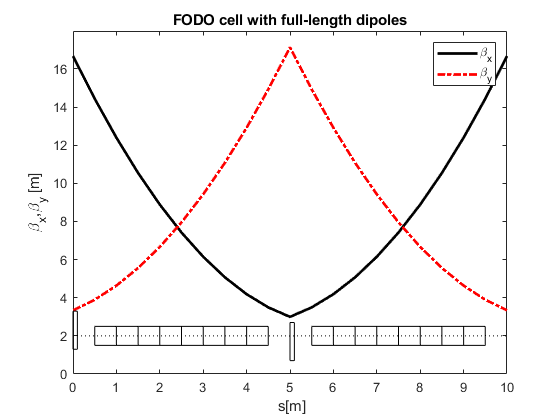

plot_betas(beamline,sigma0)
drawmag(beamline,1,2)
dlmwrite('mobius_arc_cell.bl',beamline,'\t')
title('FODO cell with full-length dipoles')

fodo90m=beamline;  % save the matched beamline

## Dispersion suppressor

Now we calculate the periodic dispersion to later use it as the starting dispersion for the dispersion suppressor.

D0=periodic_dispersion(Rturn);

The FODO cells in the disperson suppressor have only half-length dipoles and we therefore build a cell fodo_ds to describe it. We only have to change the repeat codes of the drift spaces and dipole segments.

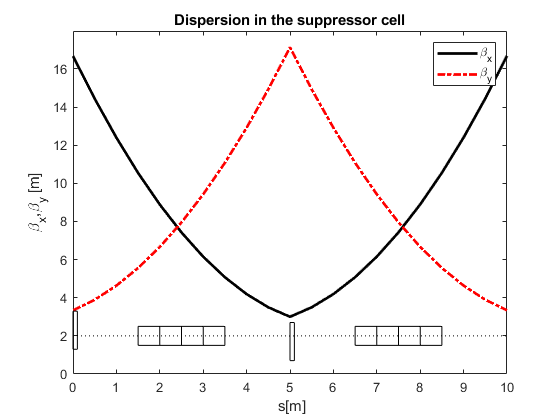

fodo_ds=fodo90m;  % base teh dispersion supporessor on the matched arc cell
fodo_ds(2,2)=3;
fodo_ds(3,2)=4;
fodo_ds(4,2)=3;
fodo_ds(6,2)=3;
fodo_ds(7,2)=4;
fodo_ds(8,2)=3;
beamline=fodo_ds; 
figure; plot_betas(beamline,sigma0)
drawmag(beamline,1,2)
title('Dispersion in the suppressor cell')

Now we need to match the quadrupoles in the four quadrupoles in the dispersion suppressor to make the dispersion and its derivartive to zero. The quadrupoles change only by a very small amount.

beamline=[  % two cells in the dispersion suppressor
  repmat(fodo_ds,2,1)
  ];
[Racc,spos,nmat,nlines]=calcmat(beamline);
x0=[3.5392,-3.5362];       % match dispersion to zero
[x,fval]=fminsearch(@chisq_dispersion,x0) 

x =     3.5727   -3.7445


fval = 6.1567e-14

[D,Dp]=calculate_dispersion(beamline,D0);
final_dispersion = [D(end),Dp(end)]

final_dispersion = 	1.0e+-6 *

    0.2402   -0.4659


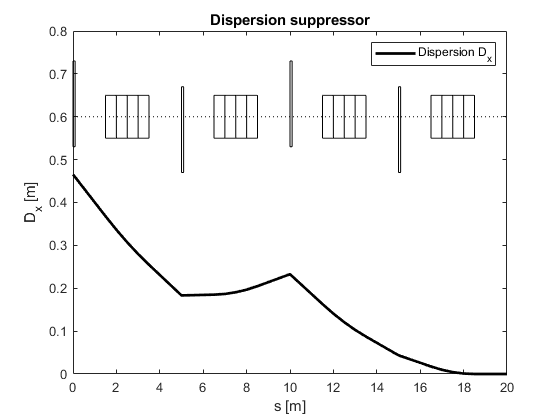

figure; plot(spos,D,'k','LineWidth',2); 
legend('Dispersion D_x')
title('Dispersion suppressor')
drawmag(beamline,0.5,0.2)
xlabel('s [m]'); ylabel('D_x [m]')

dispersion_suppressor=beamline;
Q_ds=tunes(Racc(:,:,end))

Q_ds =     0.4996    0.4600


[Racc,spos,nmat,nlines]=calcmat(beamline);

## Building the arc

Construct the arc of 43 (or 3) cells with adjacent dispersion suppressors, plot the dispersion 

narc=43  % Number of plain cells in the arc

narc = 43

beamline=[
  dispersion_suppressor;
  repmat(fodo90m,narc,1);   
  dispersion_suppressor
  ];
[Racc,spos,nmat,nlines]=calcmat(beamline);
DD0=[0;0;0;0;1];
[D,Dp]=calculate_dispersion(beamline,DD0);
final_dispersion = [D(end),Dp(end)]

final_dispersion = 	1.0e+-3 *

    0.2300    0.0317


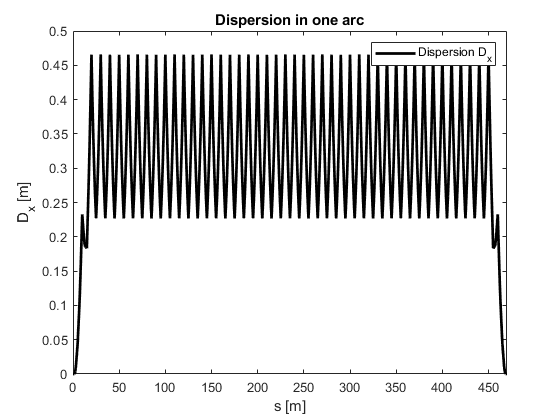

figure; plot(spos,D,'k','LineWidth',2); 
legend('Dispersion D_x'); title('Dispersion in one arc')
xlim([min(spos),max(spos)])
xlabel('s [m]'); ylabel('D_x [m]')

Q=tunes(Racc(:,:,end))

Q =     0.7497    0.8071


arc=beamline;    % save for posterity

Note that the tunes are slightly off, because we used the quads in the diuspersion suppressor to make the dispersions zero, but this slightly ($3\times 10^{-3}$) compromised the beta functions and the phase advance.

And now we also plot the beta functions, where we use the matched beta functions for the entire arc `sigma_arc`. Otherwise we can also use the periodic matric for one cell `sigma0`. 

sigma_arc=periodic_beammatrix2(Racc(:,:,end),1,1,0)

sigma_arc =    16.6749    2.3334         0         0         0
    2.3334    0.3865         0         0         0
         0         0    3.3416   -0.4676         0
         0         0   -0.4676    0.3647         0
         0         0         0         0         0


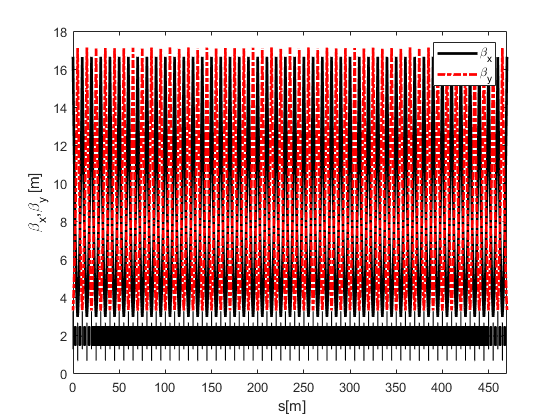

figure; plot_betas(beamline,sigma_arc); drawmag(beamline,1,2)

save('sigma_arc.mat','sigma_arc')

## Mobius straight section

### The basic cell

The two straight sections of the racetrack-shaped ring are based on the following FODO cells with $90^o$ phase advance in both planes.

cell90=[
  2,1,0,F;
  1,10,L/10,0;
  2,1,0,-F;
  1,10,L/10,0  
  ];

The beta functions and the lattice are shown with the following commands

beamline=cell90;
[Racc,spos,nmat,nline]=calcmat(beamline);
sigma_tuner=periodic_beammatrix2(Racc(:,:,end),1,1,0)

sigma_tuner =    17.0711    2.4142         0         0         0
    2.4142    0.4000         0         0         0
         0         0    2.9289   -0.4142         0
         0         0   -0.4142    0.4000         0
         0         0         0         0         0


Q_cell90=tunes(Racc(:,:,end))

Q_cell90 =     0.2500    0.2500


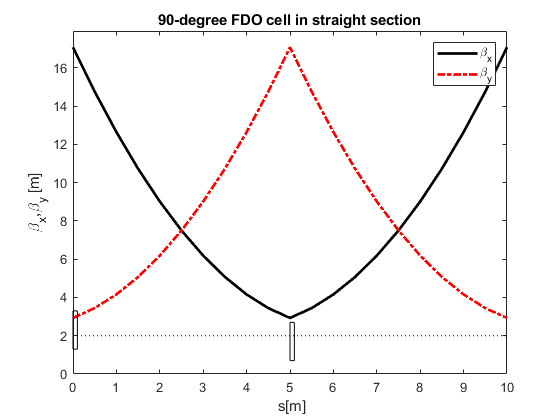

figure;  plot_betas(beamline,sigma_tuner); drawmag(beamline,1,2)
title('90-degree FDO cell in straight section')

save('sigma_tuner.mat','sigma_tuner')

We will  place the skew quadrupoles in the second half of the cell, between the defocussing and the focussing quad of the next section, where $\beta_x$ is ascending and $\beta_y$ is descending.

fodoskew=[
  2,1,0,F;
  1,10,L/10,0;
  2,1,0,-F;
  1,5,L/10,0;
 60,1,0,0;       % skew quadrupole
  1,5,L/10,0
  ];

Now we need to find the beta function at the location of the skew quadrupole. To do so, we cyclically shift the lattice by twom positions vertically, such that it starts with the skew quadrupole. Then we calculate the transfer matrices and the periodic beam matrix, which gives us the beta function that we use to set the strength of the skew quad.

fodo_from_skew=circshift(fodoskew,2);
beamline=fodo_from_skew;
[Racc,spos,nmat,nline]=calcmat(beamline);
sigma_skew=periodic_beammatrix2(Racc(:,:,end),1,1,0);  % betas at skew quad
beta0=sigma_skew(1,1)

beta0 = 7.5000

### Match arc to skew cell

And now the two cells that match from the arc to the cells with the skew quads.

match_arc_to_skew=[cell90;fodoskew];
beamline=match_arc_to_skew;
sigma_start=sigma_arc;
sigma_end=sigma_tuner;
x0=[3.5,-3.5,3.5,-3.5];
[x,fval]=fminsearch(@chisq_betafunctions_skew,x0)

x =     3.5572   -3.5649    3.5384   -3.4692


fval = 3.4197e-07

skew_straight_in=beamline

skew_straight_in =     2.0000    1.0000         0    3.5573
    1.0000   10.0000    0.5000         0
    2.0000    1.0000         0   -3.5649
    1.0000   10.0000    0.5000         0
    2.0000    1.0000         0    3.5385
    1.0000   10.0000    0.5000         0
    2.0000    1.0000         0   -3.4692
    1.0000    5.0000    0.5000         0
   60.0000    1.0000         0         0
    1.0000    5.0000    0.5000         0


Now this only works reasonably well. The `fval` is below $10^{-6}$.

### Match skew to arc cell

In the next step we adjust the four quadrupoles in two cells to match the $90^o$ cells with the skew quadrupoles to the arc cells

match_skew_to_arc=repmat(cell90,2,1);
beamline=match_skew_to_arc;
[Racc,spos,nmat,nline]=calcmat(beamline);

We use the periodic beta functions in the cells as the starting value `sigma0` and the beta functions in the arc are passed to the fiting routine as the global variable `sigma_arc`.

sigma_start=sigma_tuner;
sigma_end=sigma_arc;
x0=[3.5,-3.5,3.5,-3.5]; %+randn(1,4); 
[x,fval]=fminsearch(@chisq_betafunctions_skew,x0) 

x =     3.5267   -3.4723    3.5447   -3.5682


fval = 8.5103e-07

skew_straight_out=beamline

skew_straight_out =     2.0000    1.0000         0    3.5267
    1.0000   10.0000    0.5000         0
    2.0000    1.0000         0   -3.4724
    1.0000   10.0000    0.5000         0
    2.0000    1.0000         0    3.5447
    1.0000   10.0000    0.5000         0
    2.0000    1.0000         0   -3.5682
    1.0000   10.0000    0.5000         0


And now we can define the `mobius_straight`, but first turn the skew quads on and choose by how much they are turned on to their default value.

skew_quads_on=1   % 1=on or 0=off

skew_quads_on = 1

skew_quad_strength=0 % slider to adjust the skew strength

skew_quad_strength = 0

It's the focal length and that is inversely proportional to the excitation. Moreover, catch the case when the skew quad is turned off.

scale_factor=0;
if abs(skew_quad_strength)>0, scale_factor=1/skew_quad_strength; end
if skew_quads_on
  fodoskew(5,4)=scale_factor*beta0;
  skew_straight_in(9,4)=scale_factor*beta0;
end

and now the definition

mobius_straight=[
  skew_straight_in;
  fodoskew;
  fodoskew;
  skew_straight_out
  ];

and then propagate sigma_arc through this section

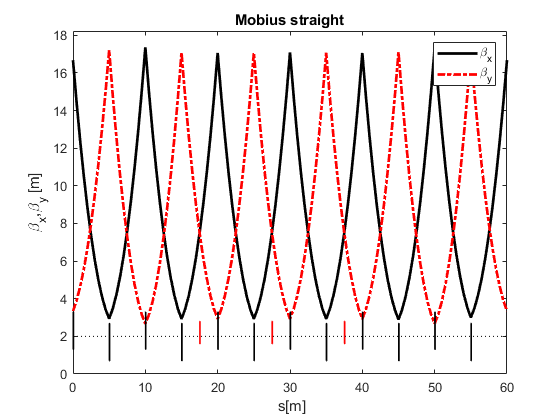

beamline=mobius_straight;
[Racc,spos,nmat,nline]=calcmat(beamline); 
figure; plot_betas(beamline,sigma_arc); drawmag(beamline,1,2)
title('Mobius straight')

Rend=Racc(:,:,end)

Rend =    -1.0582    0.4166         0         0         0
   -0.0097   -0.9411         0         0         0
         0         0   -1.0226   -0.1708         0
         0         0    0.0186   -0.9748         0
         0         0         0         0    1.0000


sigtmp=Rend*sigma_arc*Rend'

sigtmp =    16.6828    2.3346         0         0         0
    2.3346    0.3866         0         0         0
         0         0    3.3418   -0.4675         0
         0         0   -0.4675    0.3647         0
         0         0         0         0         0


Bmag=BmagBoth(sigtmp,sigma_arc)

Bmag = 	1.0e+-6 *

    0.1110    0.0081


Qmobius=tunes(Rend)

Qmobius =     0.4960    0.5081


## Build tuner section of 3 x 2 cells

part1=repmat(cell90,2,1); part2=part1; part3=part1;

and use the second one part2 as the central part to adjust the tune. Make this a $(\phi_x ,\phi_y)$ cell

beamline=cell90;
Qx=0.2;
Qy=0.2;
x0=[3.5,-3.5];
[x,fval]=fminsearch(@chisq_tunes_part,x0)

x =     4.2532   -4.2532


fval = 6.1873e-12

part2=[beamline;beamline];    
[Racc,spos,nmat,nline]=calcmat(beamline);
Rend=Racc(:,:,end)

Rend =    -1.5576   15.8779         0         0         0
   -0.2764    2.1756         0         0         0
         0         0    0.7936    4.1221         0
         0         0   -0.2764   -0.1756         0
         0         0         0         0    1.0000


Q=tunes(Rend)

Q =     0.2000    0.2000


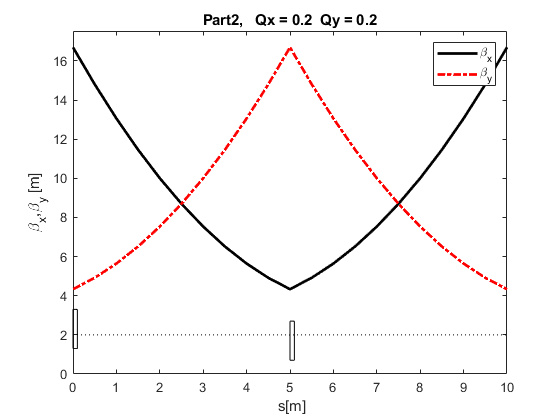

sigma_part2=periodic_beammatrix2(Rend,1,1,0);
figure; plot_betas(beamline,sigma_part2); drawmag(beamline,1,2)
title(['Part2,   Qx = ',num2str(Q(1)),'  Qy = ',num2str(Q(2))])

and now match the arc to this section

beamline=part1;
sigma_start=sigma_arc;
sigma_end=sigma_part2;
x0=[3.5,-3.5,3.5,-3.5]; %+randn(1,4); 
[x,fval]=fminsearch(@chisq_betafunctions_skew,x0)

x =     3.3278   -3.4588    3.5875   -3.6534


fval = 2.6846e-10

part1=beamline;

and the reverse section to get from part2 back to the arc

beamline=part3;
sigma_start=sigma_part2;
sigma_end=sigma_arc;
x0=[3.5,-3.5,3.5,-3.5]; %+randn(1,4); 
[x,fval]=fminsearch(@chisq_betafunctions_skew,x0)

x =     3.6784   -3.5749    3.4083   -3.3911


fval = 1.0336e-09

part3=beamline;

now combine the sections 

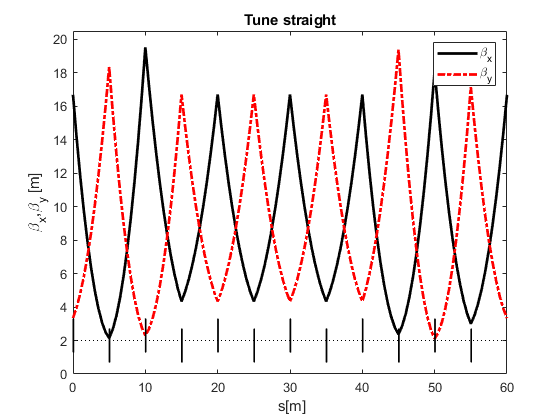

tuner_straight=[
  part1;
  part2;
  part3
  ];
beamline=tuner_straight;
[Racc,spos,nmat,nline]=calcmat(beamline);
figure; plot_betas(beamline,sigma_arc); drawmag(beamline,1,2)
title('Tune straight')

Rend=Racc(:,:,end); Q=tunes(Rend)

Q =     0.4171    0.4061


sigma=Rend*sigma_arc*Rend';
Bmag=BmagBoth(sigma,sigma_arc)

Bmag = 	1.0e+-8 *

    0.0328    0.1122


Now define the ring and fix the tune

ring=[
  mobius_straight;
  arc;
  tuner_straight;  
  arc
  ];
ring2=[
  tuner_straight;    
  arc;
  mobius_straight; 
  arc
  ];
beamline=ring;
[Racc,spos,nmat,nlines]=calcmat(beamline); Rend=Racc(:,:,end);
Q=tunes(Rend)

Q =     0.4126    0.5283


Plot betafunctions

flipped=0;
show=1

show = 1

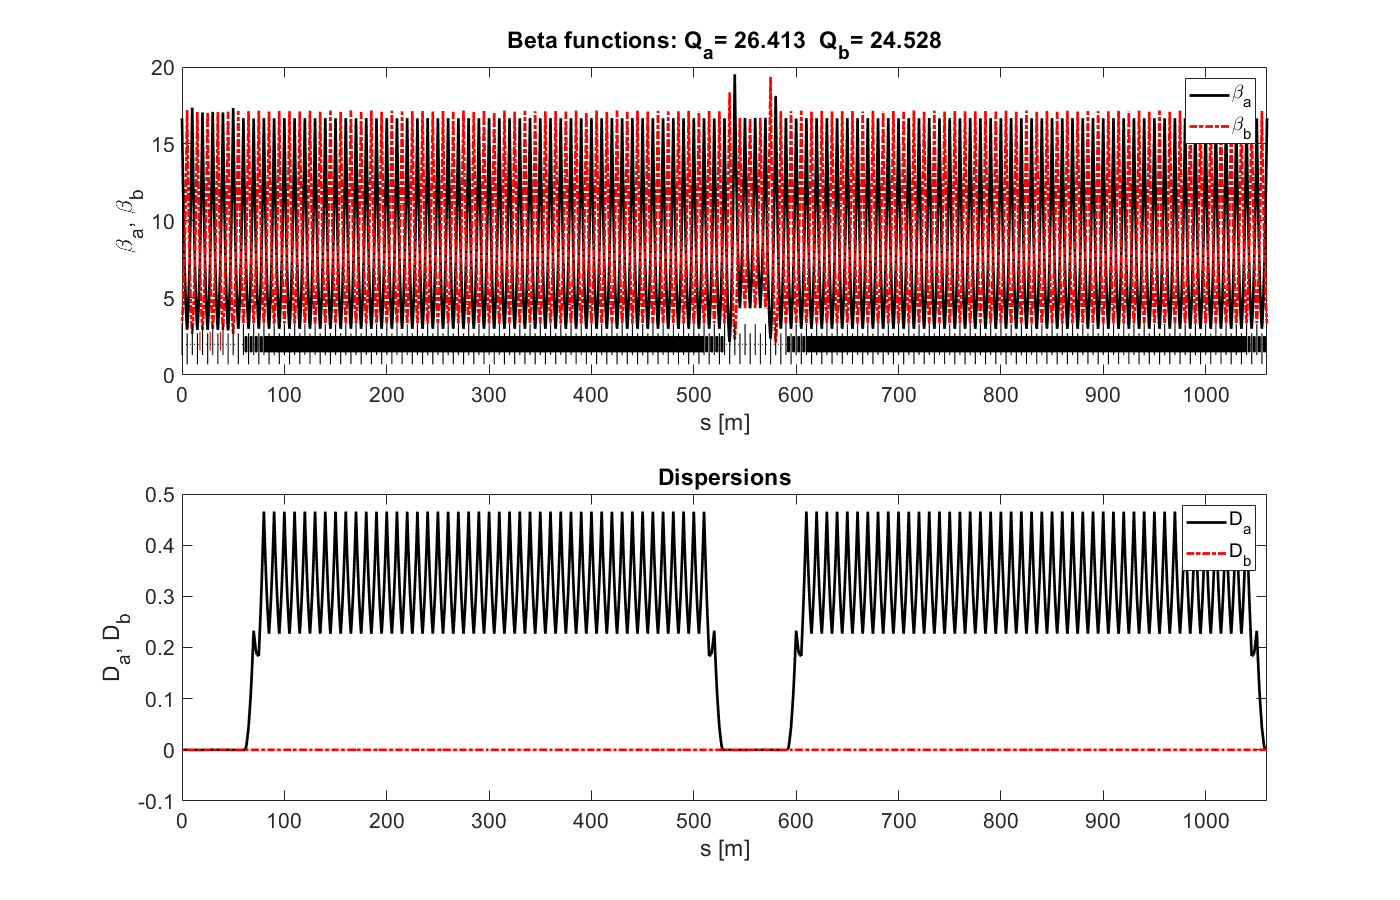

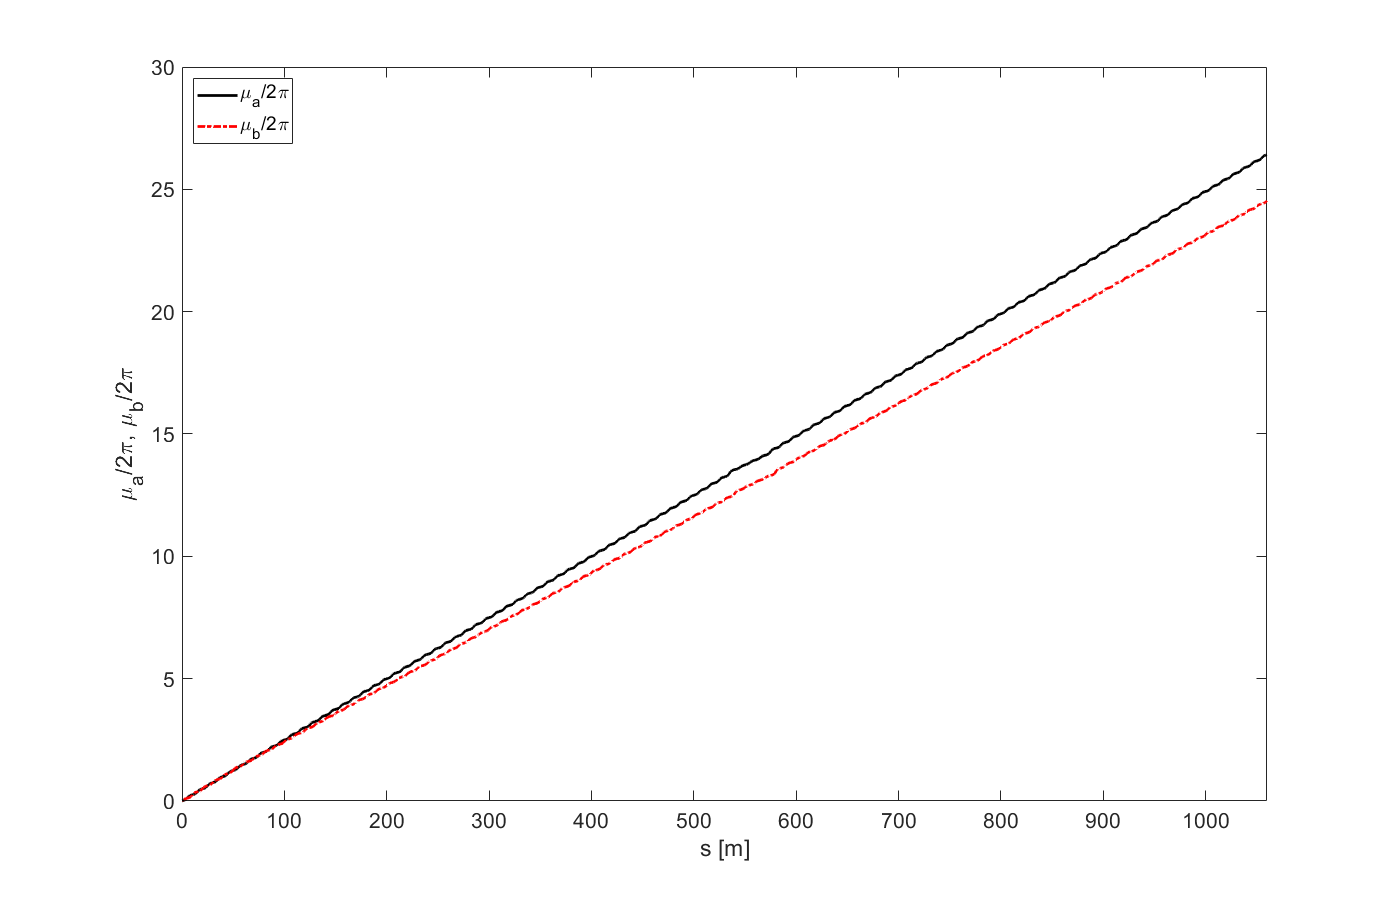

[beta1,beta2,disp,Qtune]=plot_betas_unrolled(beamline,flipped,show);

Qtunes=Qtune(end,:)

Qtunes =    26.4126   24.5283


Slice the elements and calculate the radiation integrals

beamline=dipole_slicer(beamline,100);
[I1,I2,I3,I4,I5]=radiation_integrals(beamline,flipped);

Then use the integrals to calculate the momentum compaction factor $\alpha$, the momentum spread $\sigma_p$, the three damping times $\tau_x,\tau_y,\tau_p$, and the eigenemittances $\varepsilon_1$ and $\varepsilon_2$.

E0=10000;     % 10 GeV
C=spos(end);  % Circumference
[alpha,sigp,tau,eps]=beam_parameters(E0,C,I1,I2,I3,I4,I5);

Then calculate the periodic beammatrix $\sigma_0$ for the emittances just calculated and display the beam sizes.

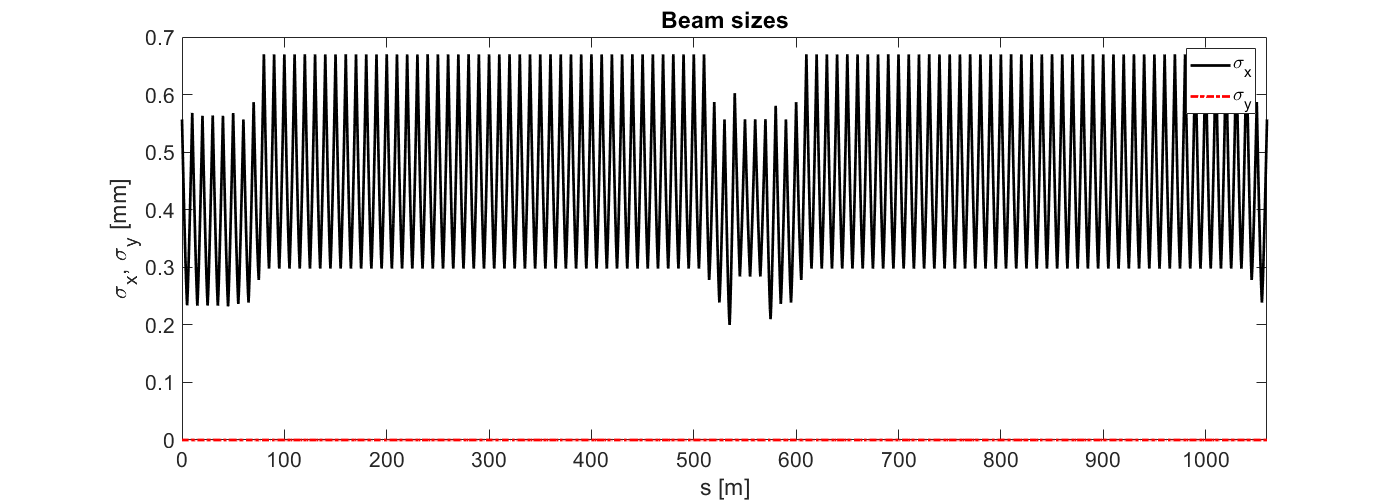

[Racc,spos,nmat,nlines]=calcmat(beamline); Rend=Racc(:,:,end);
sigma0=periodic_beammatrix2(Rend,eps(1),eps(2),sigp);
figure; plot_sigmamatrix(beamline,sigma0);

Finally display all parameters

[Racc,spos,nmat,nlines,ibl]=calcmat(beamline);
Rturn=Racc(:,:,end)

Rturn =    -2.0707    8.7001         0         0    0.0003
   -0.2017    0.3646         0         0    0.0000
         0         0   -1.0670   -0.5913         0
         0         0    0.0645   -0.9014         0
         0         0         0         0    1.0000


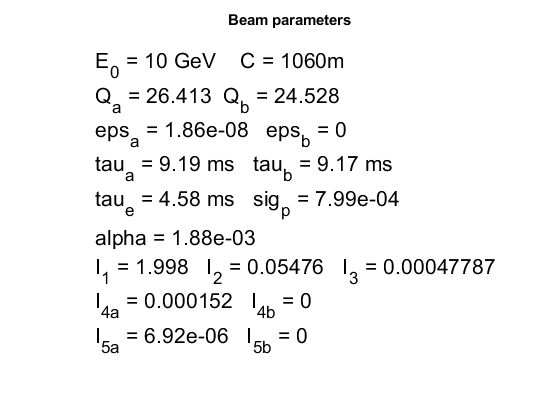

[O,A,T,p]=sagrub(Rturn,flipped);
figure
box on
text(0.05,0.9,['E_0 = ',num2str(E0/1e3),' GeV    C = ',num2str(C), 'm'],'FontSize',16)
text(0.05,0.8,['Q_a = ',num2str(Qtune(end,1),5),'  Q_b = ',num2str(Qtune(end,2),5)],'FontSize',16)
text(0.05,0.7,['eps_a = ',num2str(eps(1),3),'   eps_b = ',num2str(eps(2),3)],'FontSize',16) 
text(0.05,0.6,['tau_a = ',num2str(tau(1)*1e3,3),' ms   tau_b = ',num2str(tau(2)*1e3,3),' ms'],'FontSize',16) 
text(0.05,0.5,['tau_e = ',num2str(tau(3)*1e3,3),' ms   sig_p = ',num2str(sigp,'%.2e')],'FontSize',16) 
text(0.05,0.4,['alpha = ',num2str(alpha,'%.2e')],'FontSize',16) 
text(0.05,0.3,['I_1 = ',num2str(I1),'   I_2 = ',num2str(I2),'   I_3 = ',num2str(I3)],'FontSize',16) 
text(0.05,0.2,['I_{4a} = ',num2str(I4(1),3),'   I_{4b} = ',num2str(I4(2),3)],'FontSize',16) 
text(0.05,0.1,['I_{5a} = ',num2str(I5(1),3),'   I_{5b} = ',num2str(I5(2),3)],'FontSize',16) 
title('Beam parameters')
axis off

Now save the world

save('MR0_beamline.mat','beamline','E0','C','beta0','flipped')
toc

Elapsed time is 19.318293 seconds.


## Appendix

#### chisq_tunes()

The function `chisq_tunes()` is used when matching the tunes of the FODO cell. It receives the focal lengths of the two quadrupoles in the array `x` as input and returns the squared difference to the desired tune values, which are passed as global variables `Qx` and `Qy` to this function. 

function chisq=chisq_tunes(x)
global beamline sigma0 D0    % need info about the beamline
global Qx Qy
beamline(1,4)=x(1);   % change quadrupole excitations
beamline(5,4)=x(2);
[Racc,spos]=calcmat(beamline);
Rturn=Racc(:,:,end); 
[QQx,alpha0x,beta0x,gamma0x]=R2beta(Rturn(1:2,1:2));
[QQy,alpha0y,beta0y,gamma0y]=R2beta(Rturn(3:4,3:4));
chisq=(Qx-QQx)^2+(Qy-QQy)^2; % desired tunes
end

#### chisq_dispersion()

The function `chisq_dispersion()` receives the focal lengths of the quadrupoles in the dispersions suppressor in the array `x` as input and returns the squared difference of the horizontal dispersion as `chisq`.

function chisq=chisq_dispersion(x)
global beamline sigma0 D0     % need info about the beamline
beamline(1,4)=x(1);  % change quadrupole excitations
beamline(9,4)=x(1);
beamline(5,4)=x(2);
beamline(13,4)=x(2);
[Racc,spos,nmat,nlines]=calcmat(beamline);
Rturn=Racc(:,:,end);
D=Rturn*D0;
chisq=D(1)^2+D(2)^2; % dispersion zero
end

#### chisq_betafunctions_skew()

The function `chisq_betafunction_skew()` is used to match the Mobius and the tuner straight section to the arcs. It receives the focal lengths of the quadrupoles in the two matching cells adjacent to the arc in the array `x` as input and returns the squared difference of the mismatch parameter `Bmag()`  as `chisq`.

function chisq=chisq_betafunctions_skew(x)
global beamline sigma0 D0      % need info about the beamline
global sigma_start sigma_end
betax=sigma_end(1,1); alfax=-sigma_end(1,2);
betay=sigma_end(3,3); alfay=-sigma_end(3,4);
beamline(1,4)=x(1);  % change quadrupole excitations
beamline(3,4)=x(2);
beamline(5,4)=x(3);
beamline(7,4)=x(4);
[Racc,spos,nmat,nlines]=calcmat(beamline); Rend=Racc(:,:,end); 
sigma=Rend*sigma_start*Rend';
% chisq=(sigma(1,1)-betax)^2+(sigma(1,2)+alfax)^2 ...
%  +(sigma(3,3)-betay)^2+(sigma(3,4)+alfay)^2;
chisq=Bmags(sigma_end(1:2,1:2),sigma(1:2,1:2)) ...
  +Bmags(sigma_end(3:4,3:4),sigma(3:4,3:4))-2;
end

#### Bmags()

The function `Bmags()` receives two $2\times 2$ beam matrices `sig1` and `sig2` as input and returns the mismatch parameter Bmag, which is defined in Equation 8.15 in [V. Ziemann, `Hands-on accelerator physics...`].

function out=Bmags(sig1,sig2)
eps1=sqrt(det(sig1)); beta1=sig1(1,1)/eps1; alpha1=-sig1(1,2)/eps1;
eps2=sqrt(det(sig2)); beta2=sig2(1,1)/eps2; alpha2=-sig2(1,2)/eps2;
out=0.5*(beta1/beta2+beta2/beta1+beta1*beta2*(alpha1/beta1-alpha2/beta2)^2);
end

#### BmagBoth()

The function `BmagBoth()` receives two $4\times 4$ beam matrices as input and returns the sum of the horizontal `Bmags` and the vertical `Bmags`, with unity subtracted such that the matched beams return zero.

function Bmag=BmagBoth(sig1,sig2)
Bmag=[Bmags(sig1(1:2,1:2),sig2(1:2,1:2))-1, ...
  Bmags(sig1(3:4,3:4),sig2(3:4,3:4))-1];
end

#### chisq_tunes_part()

The function chisq_tunes_part()  is used to match the tunes of the central cells in the tuner straight. It receives the focal lengths of the quadrupoles in the array `x` as input and returns the squared difference to the desired tune values, which are passed as global variables `Qx` and `Qy` to this function. 

function chisq=chisq_tunes_part(x)
global beamline sigma0 D0    % need info about the beamline
global Qx Qy 
beamline(1,4)=x(1);  
beamline(3,4)=x(2);
[Racc,spos]=calcmat(beamline);
Rturn=Racc(:,:,end); 
[QQx,alpha0x,beta0x,gamma0x]=R2beta(Rturn(1:2,1:2));
[QQy,alpha0y,beta0y,gamma0y]=R2beta(Rturn(3:4,3:4));
chisq=(Qx-QQx)^2+(Qy-QQy)^2; % desired tunes
end